# Example 5

#### Problem OCP (Brachistochrone):

## Implementation:

clear all
close all

### Load Parameters

CONSTANTS.N = 15;
CONSTANTS.a = 0;
CONSTANTS.b = 10;
CONSTANTS.h = 10;
CONSTANTS.g = 9.81;

### Initial Guess

N = CONSTANTS.N; 
x1 = rand(N+1,1);
x2 = rand(N+1,1);
u1 = rand(N+1,1);
u2 = rand(N+1,1);
tf = 10;
x0 = [ x1 ; x2 ; u1 ; u2 ; tf ];

### Linear Constraints and UL bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

### Optimize (fmincon)

options = optimoptions(@fmincon,'Algorithm','sqp', ... 
    'MaxFunctionEvaluations',3000000, 'StepTolerance', 1e-10);
tic
[x,f] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 0.716360 seconds.


### Plot

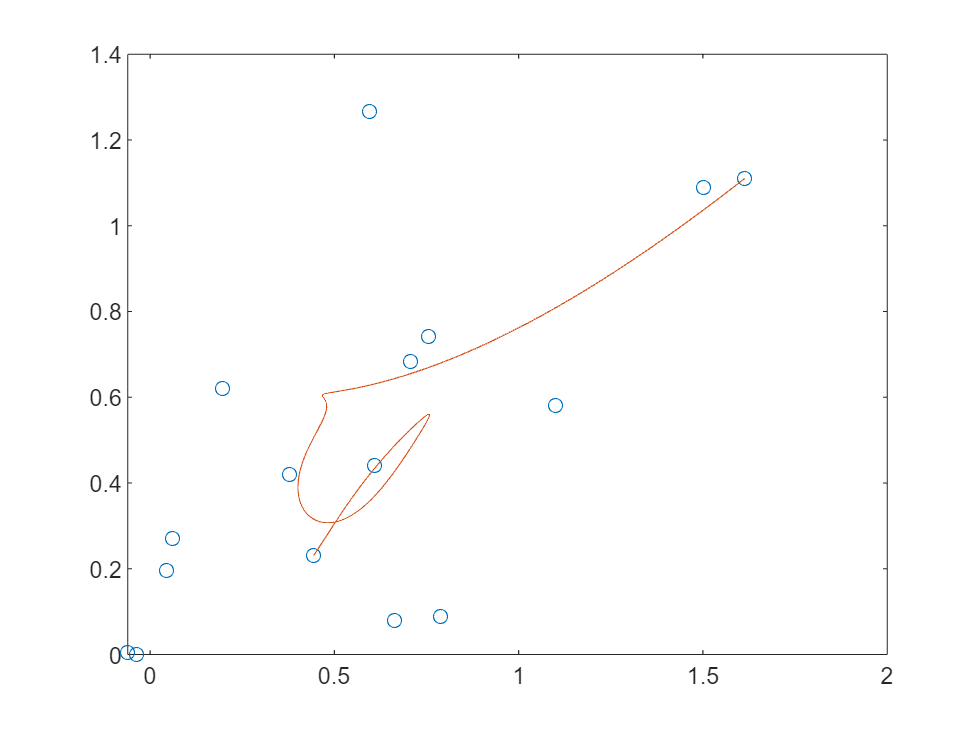

N = CONSTANTS.N; 
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
u1 = x(2*N+3:3*N+3);
u2 = x(3*N+4:4*N+4);
tf = x(end);

[tnodes,~,~] = BeBOT(N,tf);
t = 0:0.01:tf;

figure
plot(x1,x2,'o'); hold on
plot(BernsteinPoly(x1,t),BernsteinPoly(x2,t));

### Cost function

function J = costfun(x,CONSTANTS)
%COSTFUN Summary of this function goes here
N = CONSTANTS.N; 
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
u1 = x(2*N+3:3*N+3);
u2 = x(3*N+4:4*N+4);
tf = x(end);



J = tf;
end

### Nonlinear Constraint

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N; 
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
u1 = x(2*N+3:3*N+3);
u2 = x(3*N+4:4*N+4);
tf = x(end);

[~,~,Diff] = BeBOT(N,tf);

g = CONSTANTS.g;
a = CONSTANTS.a;
b = CONSTANTS.b;
h = CONSTANTS.h;

dyn1 = (x1'*Diff)' - u1.*sqrt(2*g*x2);
dyn2 = (x2'*Diff)' - u2.*sqrt(2*g*x2);

nonlcon1 = u1.^2 + u2.^2 - 1;

c=[];
ceq=[dyn1; dyn2; nonlcon1; x1(1) - a; x2(1); x1(end) - b; x2(end) - h];
end